# Exercise 4.3 - Noise in nature

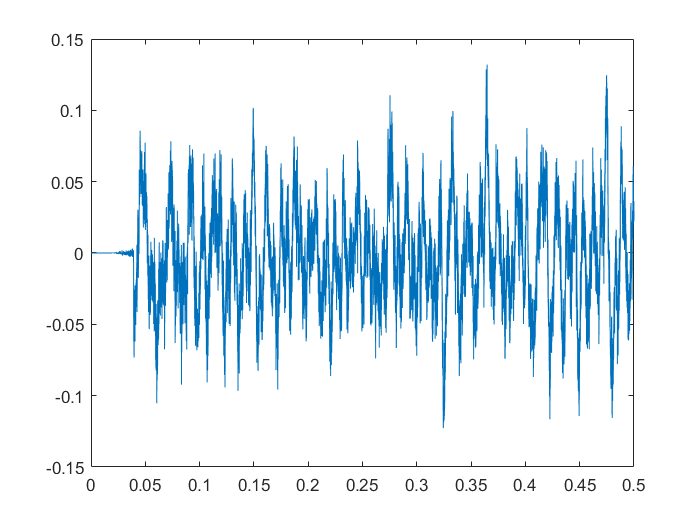

% Import audio files.
[rainThunder, fs1] = audioread('audio\rain-and-thunder.mp3');
[windBlowing, fs2] = audioread('audio\wind-blowing.wav');
[rainStorm, fs3] = audioread('audio\rainstorm.aiff');

% Trim fragments of 500 ms (time domain).
N1 = 0.5 * fs1; % # samples (rain / storm).
rainThunderFrag = rainThunder(1 : N1);
N2 = 0.5 * fs2; % # samples (wind whistling).
windBlowingFrag = windBlowing(1 : N2);
N3 = 0.5 * fs3; % # samples (rain).
rainStormFrag = rainStorm(1 : N3);

% Play trimmed audio fragments.
%sound(rainThunderFrag, fs1);
%sound(windBlowingFrag, fs2);
sound(rainStormFrag, fs3);

% Allocate vectors with the right sizes to plot the fragments in the time domain.
n1 = 0 : N1 - 1;
n2 = 0 : N2 - 1;
n3 = 0 : N3 - 1;

% Plot all three fragments.
t1 = n1 / fs1;
plot(t1, rainThunderFrag);

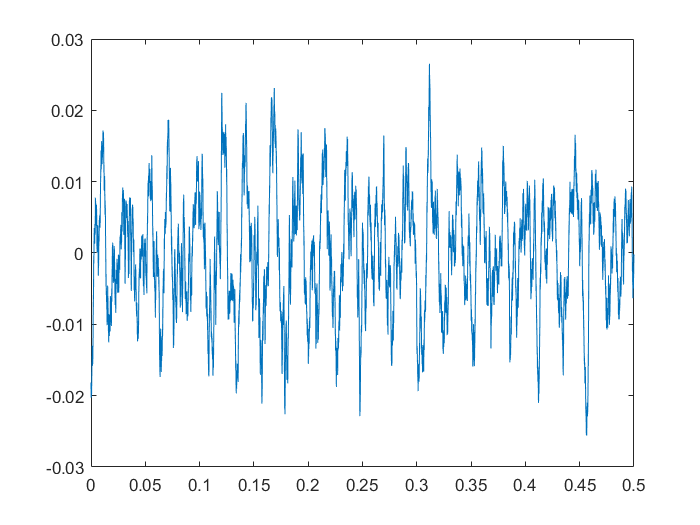

t2 = n2 / fs2;
plot(t2, windBlowingFrag);

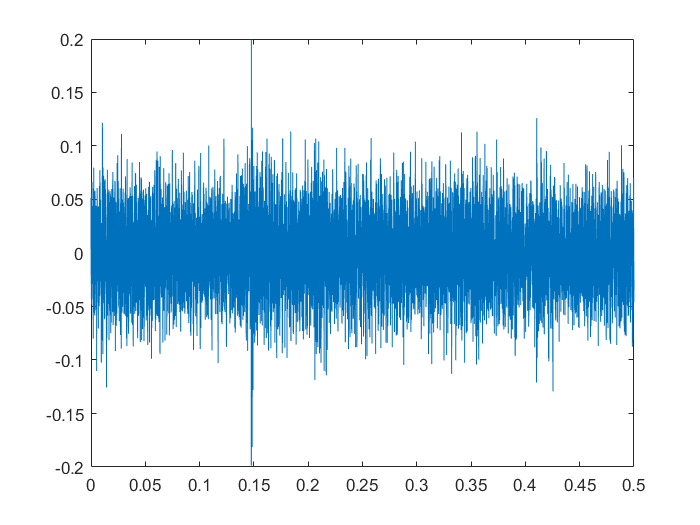

t3 = n3 / fs3;
plot(t3, rainStormFrag);

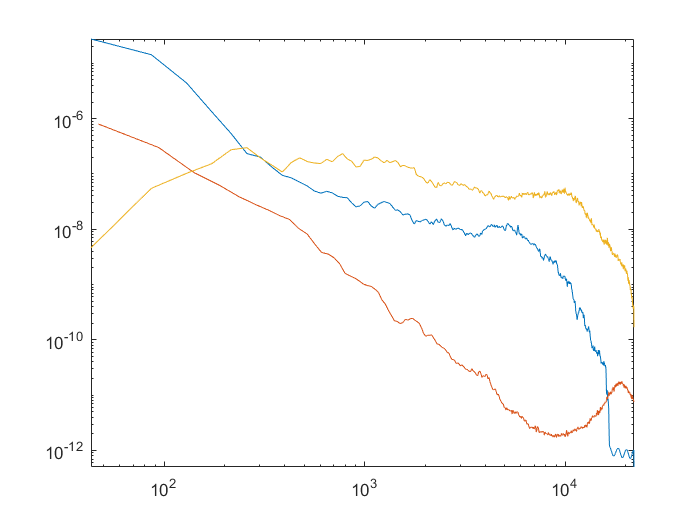


% Trim fragments of 7 seconds, in order to avoid long processing times and
% so that they all have the same length, making it easier to plot them
% together.
rainThunderFrag2 = rainThunder(1 : (7 * fs1));
windBlowingFrag2 = windBlowing(1 : (7 * fs2));
rainStormFrag2 = rainStorm(1 : (7 * fs3));

% SPECTRAL ANALYSIS
% Estimate Power Spectral Density (PSD).
[Pxx1, f1] = pwelch(rainThunderFrag2, 1000, 0, [], fs1);
[Pxx2, f2] = pwelch(windBlowingFrag2, 1000, 0, [], fs2);
[Pxx3, f3] = pwelch(rainStormFrag2, 1000, 0, [], fs3);

% Plot DSP, to see the distribution of power as a function of frequency. 
% We shall use logarithmic scale.
loglog(f1, Pxx1), hold on,
loglog(f2, Pxx2), 
loglog(f3, Pxx3)
axis([0 fs1/2 -inf inf]);